# Exam 2 Review

#### Problem 1: 

Consider Points (0,20), (1,7), (2,0)

a) Least Squares

b) Exponential form $y=C+D*2^{-x}$


$$ln(y)=ln(C) - (ln(D)ln(2))*x$$


c) Plot Line and Curve, Compare Them

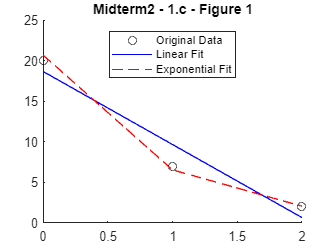

% Original Data 
x=[0 1 2];
y=[20 7 2];

% Linear Fit 
p_lin = polyfit(x, y, 1); 
y_lin = polyval(p_lin, x);

% Exponential Fit 
y_log = log(y);
p_exp = polyfit(x, y_log, 1);
y_exp = exp(polyval(p_exp, x));

% Plot Difference
figure(1); clf; hold on; 
title('Midterm2 - 1.c - Figure 1');
legend('Location', 'best');
plot(x, y, 'ko', 'DisplayName', 'Original Data');
plot(x, y_lin, 'b-', 'DisplayName', 'Linear Fit');
plot(x, y_exp, 'r--', 'DisplayName', 'Exponential Fit');
hold off; 

As shown in the graph, the exponential model gives a better fit of the data than the linear model.